clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',6);
set(0,'DefaultTextFontsize',6);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [15,15,16,5];
figpos = [0.06 0.17 0.87 0.75];
lw = 0.8;

load("data\fig6_esn50nodecontribution.mat");
nodecontributiondata = cell(6,1);

nodecontributiondata{1} = abs(Wout_lorenz(10:end)).*sum(abs(internalState_lorenz),2)';
nodecontributiondata{2} = abs(Wout_sin(10:end)).*sum(abs(internalState_sin),2)';
nodecontributiondata{3} = abs(Wout_PC3(3:end)).*sum(abs(internalState_PC3),1);
nodecontributiondata{4} = abs(Wout_PC1(3:end)).*sum(abs(internalState_PC1),1);
nodecontributiondata{5} = abs(Wout_STM3(3:end)).*sum(abs(internalState_STM3),1);
nodecontributiondata{6} = abs(Wout_STM1(3:end)).*sum(abs(internalState_STM1),1);

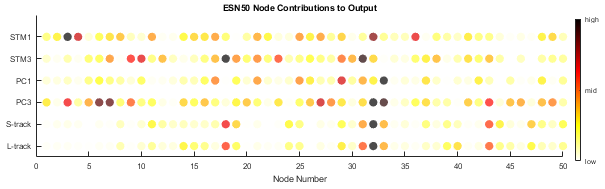

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
% set(gca,'Position', [0.13 0.17 0.75 0.75]);
set(gcf,'Visible','on');

for i = 1:6
ax(i) = axes;
data = nodecontributiondata{i};
scatter(1:50, i*ones(50,1), 40*ones(50,1), data, 'filled', 'MarkerFaceAlpha',.7);
clim([0 max(data)]);
if i > 1
ax(i).Visible = 'off';
ax(i).XTick = [];
ax(i).YTick = [];
else
    ax(i).YTick = 1:6;
    ax(i).YTickLabel = ["L-track" "S-track" "PC3" "PC1" "STM3" "STM1"];
    ylim([0.5 6.5]);
    xlabel('Node Number');
    title('ESN50 Node Contributions to Output');
    % ax(i).YAxis.Visible = 'off';
end
end
set(ax,'Position', figpos);
linkaxes(ax);

colormap(flipud(hot));
cb = colorbar();
cb.Position = [0.95, 0.15, 0.01, 0.75];
cb.Ticks = [0 max(cb.Limits)/2 max(cb.Limits)];
cb.TickLabels = ["low" "mid" "high"];

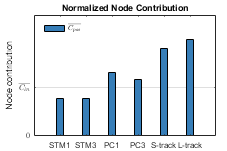

figsize = [10 15 6 4];
figpos = [0.15 0.1 0.8 0.8];

tasknames = ["STM1" "STM3" "PC1" "PC3" "S-track" "L-track"];
inputcontrilist = zeros(6,1);
pascontrilist = zeros(6,1);
for i = 1:6
    if i <= 4
        inputcontrilist(i) = mean(nodecontributiondata{7-i}(1:25));
        pascontrilist(i) = mean(nodecontributiondata{7-i}(26:end));
    else
        inputcontrilist(i) = mean(nodecontributiondata{7-i}(1:24));
        pascontrilist(i) = mean(nodecontributiondata{7-i}(25:end));
    end
end

% error in meter

c = linspecer(1);

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');
ax = gca;
% ax.YAxis.TickLabelInterpreter = 'tex';
% yaxisproperties= get(gca, 'YAxis');
% yaxisproperties.TickLabelInterpreter = 'tex'; 
% xaxisproperties= get(gca, 'XAxis');
% xaxisproperties.TickLabelInterpreter = 'none';

% x1 = (1:5) - 0.14;
% x2 = (1:5) + 0.14;
% b1 = bar(x1, inputcontrilist);
% b1.BarWidth = 0.28;
% hold on;
% b2 = bar(x2, pascontrilist);
% b2.BarWidth = 0.28;

b = bar(1:6, pascontrilist./inputcontrilist);
b.FaceColor = c;
b.BarWidth = 0.28;

xlim([0 7]);
ylim([0 2.5]);
xticks(1:6);
xticklabels(tasknames);
yticks([0 1]);
yticklabels(["0" "$\overline{C_{in}}$"]);
ylabel('Node contribution');
title("Normalized Node Contribution");

% leg = legend('$\overline{C_{pas}}$');
leg = legend('$\overline{C_{pas}}$', 'interpreter', 'latex');
leg.Box = "off";
leg.Location = "northwest";
leg.ItemTokenSize = [15 15];

ax.XGrid = 'off';
ax.YGrid = 'on';
ax.YAxis.TickLabelInterpreter = 'latex';